IK Interdisciplinary College

Linear Algebra

Lecture 2

Instructor: Emily J. King

### Moving averages of increasing window sizes

The syntax for the moving average in this demonstration is movmean(VECTOR, WINDOW_LENGTH, "Endpoints","discard").  The "Endpoints","discard" part tells Matlab to not come up for values at the endpoints.  For example, the first entry of a vector doesn't have any entries to the left of it, so you can't take an average of entries centered at the first entry.  We will ignore those values; the default in Matlab is to take averages over fewer entries at the endpoints. Other languages have different default settings.  Know what your language is doing!

Generate sine wave vector with 100 entries and visualize it.  

s=sin(2*pi*(1:100)/50);
plot(s), ylim([-1.2,1.2])

Generate noise vector with 100 entries and visualize it. 

n=0.1*randn(1,100);
plot(n), ylim([-1.2,1.2])

Make a noisy sine wave vector by adding the previous two vectors.  Then visualize the new vector.

ns=s+n;
plot(ns), ylim([-1.2,1.2])

Visualize the moving average with a window of length 3. 

The syntax for the moving average is movmean(VECTOR, WINDOW_LENGTH, "Endpoints","discard").  The "Endpoints","discard" part tells Matlab to not come up for values at the endpoints.  For example, the first entry of a vector doesn't have any entries to the left of it, so you can't take an average of entries centered at the first entry.  We will ignore those values; the default in Matlab is to take averages over fewer entries at the endpoints.

plot(movmean(ns,3,"Endpoints","discard")), ylim([-1.2,1.2])

Now, visualize the moving average with a window of length 9.

plot(movmean(ns,9,"Endpoints","discard")), ylim([-1.2,1.2])

Now, visualize the moving average with a window of length 50.

plot(movmean(ns,50,"Endpoints","discard")), ylim([-1.2,1.2])

### Convolving Pete Dog

Let's reload Pete Dog and look at him

I=imread('petedog-small.jpg');
figure, imshow(I)

Let's add some noise.

I=im2double(I);
nI=I+0.1*randn(size(I));
figure, imshow(nI)

Let's apply various Gaussian blurring. Note from Matlab documentation: The default filter size is `2*ceil(2*sigma)+1`. So setting `sigma `to 0.5 results in a 3x3 and to 1 results in a 5x5.

We'll try 0.5, 1, 2, 5, 10.

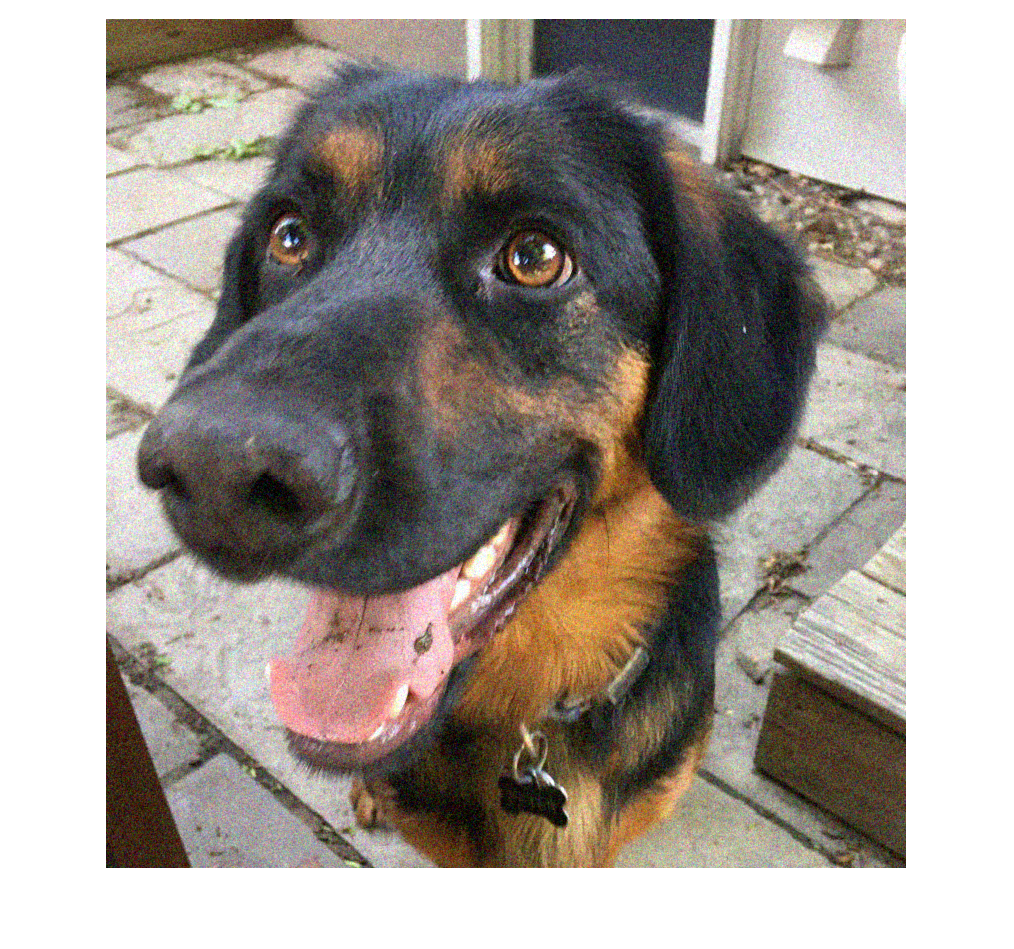

sigma=0.5
figure, imshow(imgaussfilt(nI,sigma))

Let's convolve with the Sobel filter for horizontal edges.  For each of visualization, we'll first convert the color image to a grayscale:

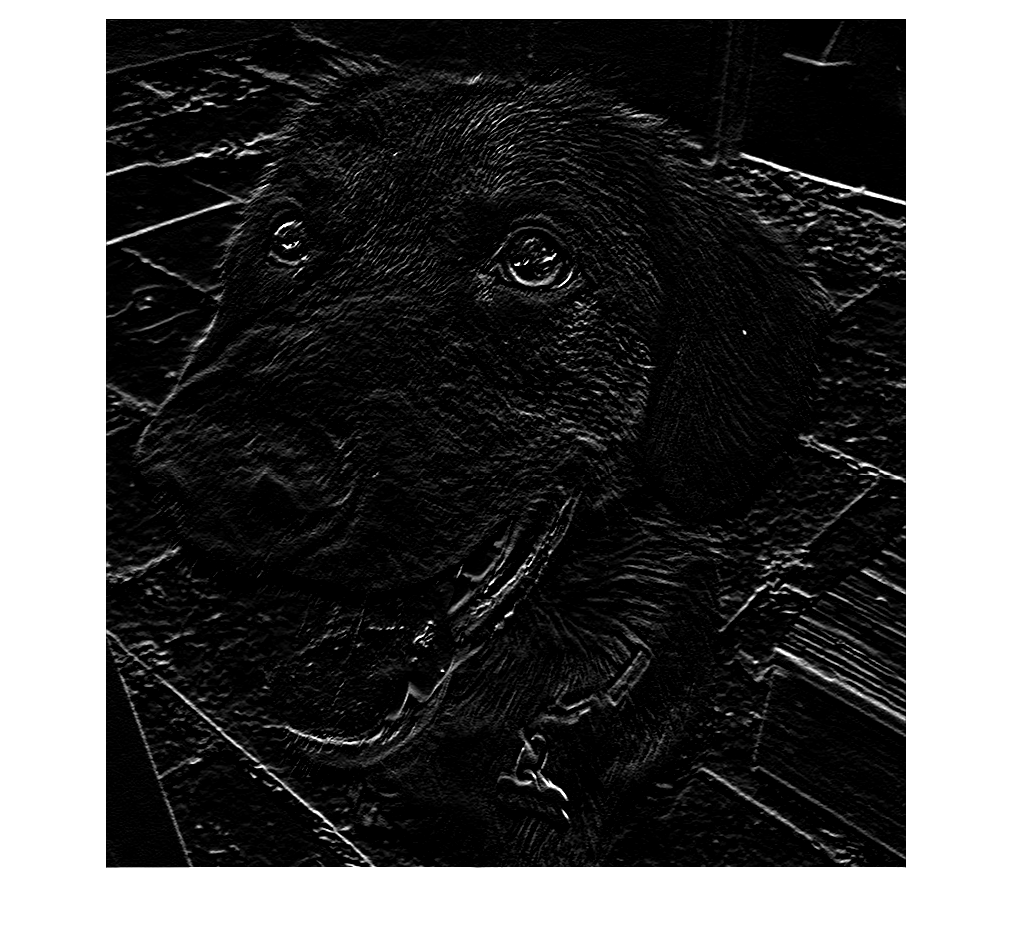

figure, imshow(imfilter(rgb2gray(I),fspecial('sobel')))

And now for vertical edges:

figure, imshow(imfilter(rgb2gray(I),fspecial('sobel')'))